# Analysis of an unbounded buffer (M/M/1)

By Pieter Cuijpers

clear all

## Introduction and outline

Our aim in this LiveScript is to compare the theoretical analysis of an M/M/1 queue with the outcome of a simulation model. In particular, we focus on the stationary distribution of the number of tokens in the system. We first repeat a theoretical analysis that is reasonably standard in literature, followed by an implementation of a simulation model in Matlab SimEvents. We compare our expectation with the outcome of the simulation model, only to find that they do not match entirely. This illustrates how a comparison is sometimes necessary to prevent the kind of oversights that occur if you only have one model to work with. Next, we solve the bug, and illustrate how simulations suffer from a warm-up time phenomenon by varying the simulation time parameter and observing that simulation gets closer to expectation as the simulation time rises. We quantify this, by performing goodness-of-fit tests, and show that the goodness-of-fit indeed improves as the simulation time increases, but only to a certain (limited) extent. We conjecture that we need more simulations in order to improve the goodness-of-fit further, but cannot get more simulations because of lack of time.

If you would like to play around with this analysis, feel free to change it. Also, I would advise you to focus on different aspects. Of course it is important to choose your simulation time long enough to compensate for the warm-up time. But once you've done this, there is no need to report on that factor anymore. Think of other parameters to vary, such as the utilization or the queue-size. And think of other metrics to evaluate, such as the sojourn-time, or anything else you find in literature.

## Theoretical analysis: The stationary token distribution in an M/M/1 queue

### Determining a stationary distribution

In [Stewart, Chap 11] an analysis is given of the distribution $p_n(t)
$of the number of elements $n$ in the system at time $t$. In this analysis, it is assumed that tokens arrive according to a Poisson process with rate $\lambda$ and are being serviced according to a Poisson distributed servicing time with mean$1/\mu$.

If we assume a sufficiently small timestep $\epsilon > 0$, then the probability of having more than 1 arrival or servicing in a time interval $(t,t+\epsilon]$ is negligible, i.e. smaller than order $o(\epsilon)$, and we may write:

        $p_0(t+\epsilon) = (1 - \lambda \epsilon+ o(\epsilon))p_0(t) +(\mu\epsilon+ o(\epsilon))p_{1}(t)$,

and

        $p_n(t+\epsilon) = (1 - \lambda \epsilon + o(\epsilon))(1 - \mu\epsilon + o(\epsilon))p_n(t) + (\lambda \epsilon + o(\epsilon))p_{n-1}(t) + (\mu\epsilon + o(\epsilon))p_{n+1}(t)$,

whenever $n>0$.

*Assuming* that the system converges to a steady state (we get back to this assumption furtheron), the steady-state distribution must equal a stationary solution with $p_n(t+\epsilon) = p_n(t)$, in other words:

        $p_0 = (1 - \lambda \epsilon)p_0 +(\mu\epsilon)p_{1} + o(\epsilon)$, and

        $p_n = (1 - \lambda \epsilon)(1 - \mu\epsilon)p_n + (\lambda \epsilon)p_{n-1} + (\mu\epsilon)p_{n+1} + o(\epsilon)$,

where $p_n$ simply represents a stationary distribution.

From this we obtain by induction that

        
$$p_n = \left( \frac{\lambda}{\mu}\right)^n p_0 + \frac{o(\epsilon)}{\mu \epsilon}$$


which for $\epsilon \rightarrow 0$ gives us

        
$$p_n = \left( \frac{\lambda}{\mu}\right)^n p_0$$


Finally, as $p_n$ is a probability distribution, we know that:

    
$$1 = \sum_{i = 0}^\infty p_i = \sum_{i = 0}^{\infty} \left(\frac{\lambda}{\mu}\right)^i p_0 = \left( \sum_{i = 0}^\infty \left(\frac{\lambda}{\mu}\right)^i\right) p_0$$


and so:

    $p_0 = \frac{1}{\sum_{i = 0}^\infty \left(\frac{\lambda}{\mu}\right)^i$   and  $p_n = \frac{\left(\frac{\lambda}{\mu}\right)^n}{\sum_{i = 0}^\infty \left(\frac{\lambda}{\mu}\right)^i$.

This is a geometric series, which is only defined if $\lambda < \mu$ and in that case solves to the so-called *geometic distribution*:

    
$$p_n = \left(\frac{\lambda}{\mu}\right)^n\left(1-\left(\frac{\lambda}{\mu}\right)\right)$$


Writing $\rho = \frac{\lambda}{\mu}$ for the utilization we get $p_n = \left(\rho\right)^n\left(1-\rho\right)$.

The geometric distribution is implemented in MATLAB by the command geopdf.

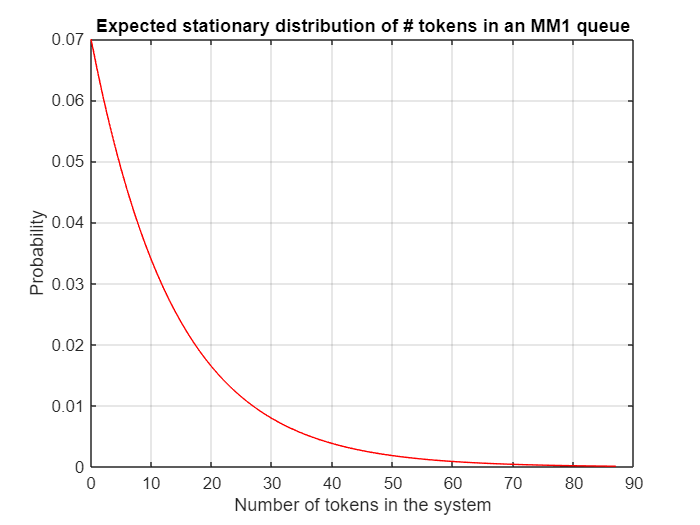

% DO NOT COPY CODE FROM THIS EXAMPLE FILE - WRITE YOUR OWN!

figure
rho =0.93;
maxn = 87;

expectedpdf = geopdf(0:maxn,1-rho);
plot(0:maxn,expectedpdf,'red')
drawnow

grid on
title('Expected stationary distribution of # tokens in an MM1 queue')
xlabel('Number of tokens in the system')
ylabel('Probability')

## Simulation: The M/M/1 queue using SimEvents

Our next step, is to validate whether an M/M/1 queue indeed behaves according to the analyzed stationary distribution. 

### Setting up the simulation parameters

We start our evaluation by studying the SimEvents model "MM1.slx" depicted below in Fig. 1.

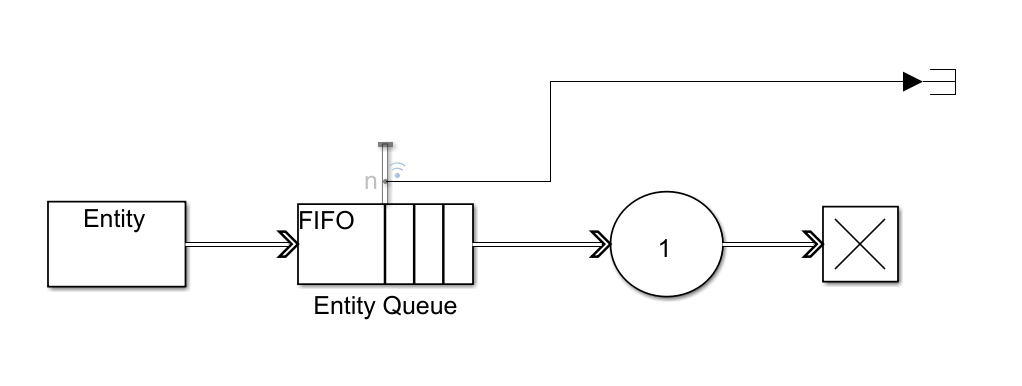

Fig 1. SimEvents model of an M/M/1 queue

In order to ensure a Poisson arrival, the entity generator and entity server have been equipped with a logarithmic choice of inter-generation times. See Fig 2.

Arguably, this is internally not the same as a 'memoryless process', as the decision point when to generate the next event lies much earlier than in a true Poisson process, but it does yield the same exponential distribution of events, so the difference cannot be concluded from observation alone. (If you have followed a course on process theory, you might consider that this model is *trace equivalent *with a Poisson process, but not *branching bisimilar. *Luckily, our performance metrics are defined in terms of traces, and not in terms of decision points, so this does not yield a problem. If you are not familiar with process theory, you may simply ignore this remark...)

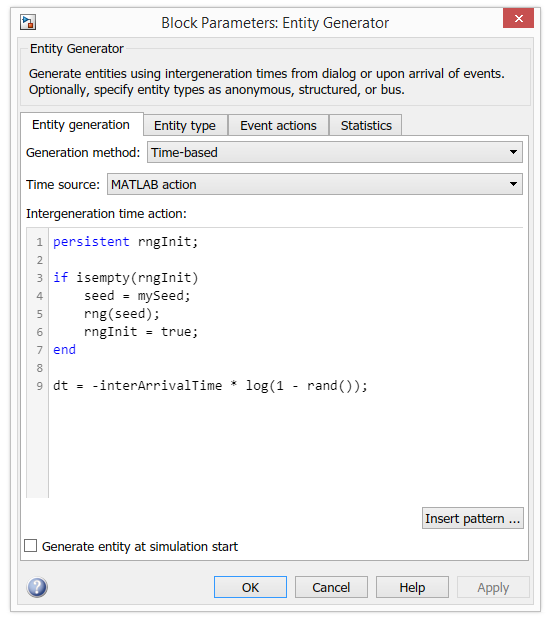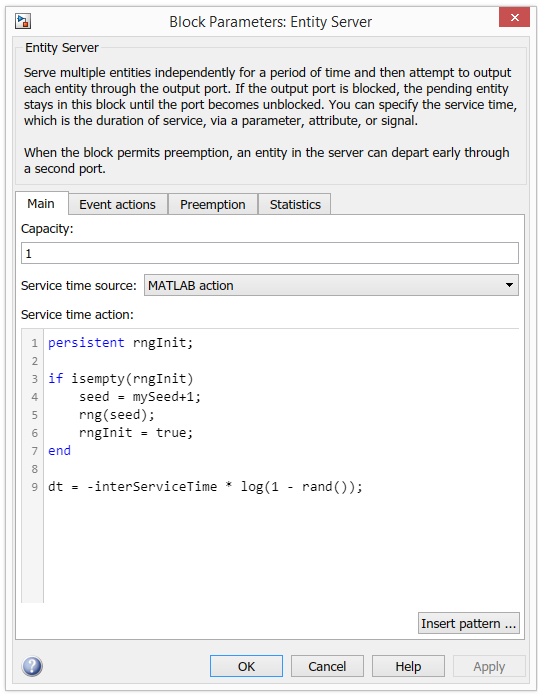

Fig 2. Settings of the entity generator and entity server

Note the use of the parameter "interArrivalTime", which we need to set in our script to ensure it is part of the Matlab environment. Programming wise, it is a good idea to make this variable globally available, so that Simulink can also access it when it is altered within Matlab function calls.

global interArrivalTime
global interServiceTime
interArrivalTime = Simulink.Parameter;
interServiceTime = Simulink.Parameter;

Furthermore, there is the parameter "mySeed" which we use to seed the randomgenerator in a controlled way.

global mySeed
mySeed = Simulink.Parameter;

*Note, that we make use of "mySeed" in the generator and of "mySeed+1" in the server, to ensure that the choice of random numbers in both is independent! In the "SimEvents tutorials" filesection on CANVAS, you can find a surprising example of dependency in QEESLab4.xlm which occurs when we neglect this detail. Using the same seed in different SimEvents blocks triggers those blocks to read random numbers from the same stream, and as both blocks start at 0, the behavior of the blocks will be statistically dependent. This is unintuitive at first sight, until one realizes that the simulation model is intended to be distributed over different processors if desired, while the use of seeds is intended to make random simulations reproducible. In a distributed implementation, each block has to be interpreted in isolation, so there is no other semantics possible that guarantees that the same choice of seed leads to the same reproducible outcome.*

To ensure the simulation of an infinite queue, we set the parameters of the entity queue block. Also, in the 'statistics tab', we enable the observation of the "Number of entities in block", and as you can see in Fig 3, we enabled "log signals" for the signal line from this output to a terminator.

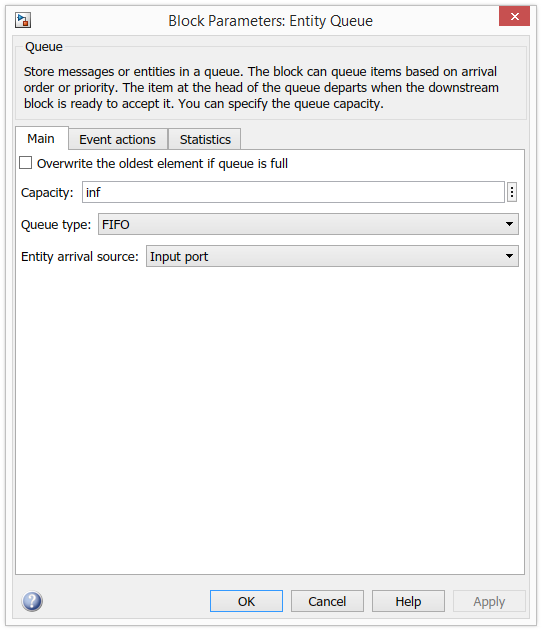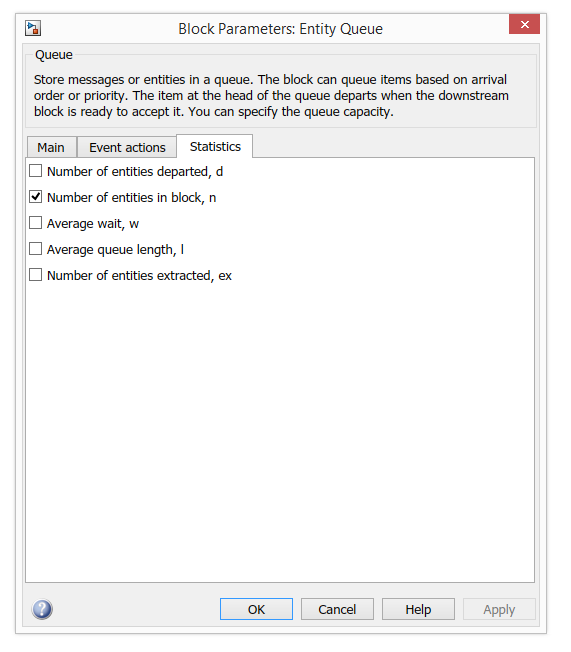

Fig 3. Settings of the entity queue

Finally, in order to be able to control the simulation time, the .slx model has been adapted with a parameter "stopTime" (see Fig. 4).

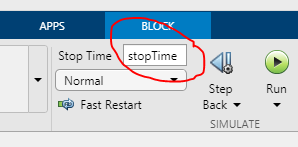

Fig 4. Setting the simulation time

% DO NOT COPY CODE FROM THIS EXAMPLE FILE - WRITE YOUR OWN!

global stopTime
stopTime = Simulink.Parameter;

And the simulation solver settings in the "model settings" tab are set to "discrete", with Zero-crossing control "disabled". This speeds up the simulation somewhat. (See Fig. 5)

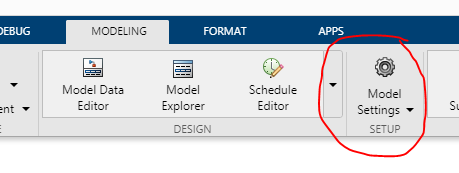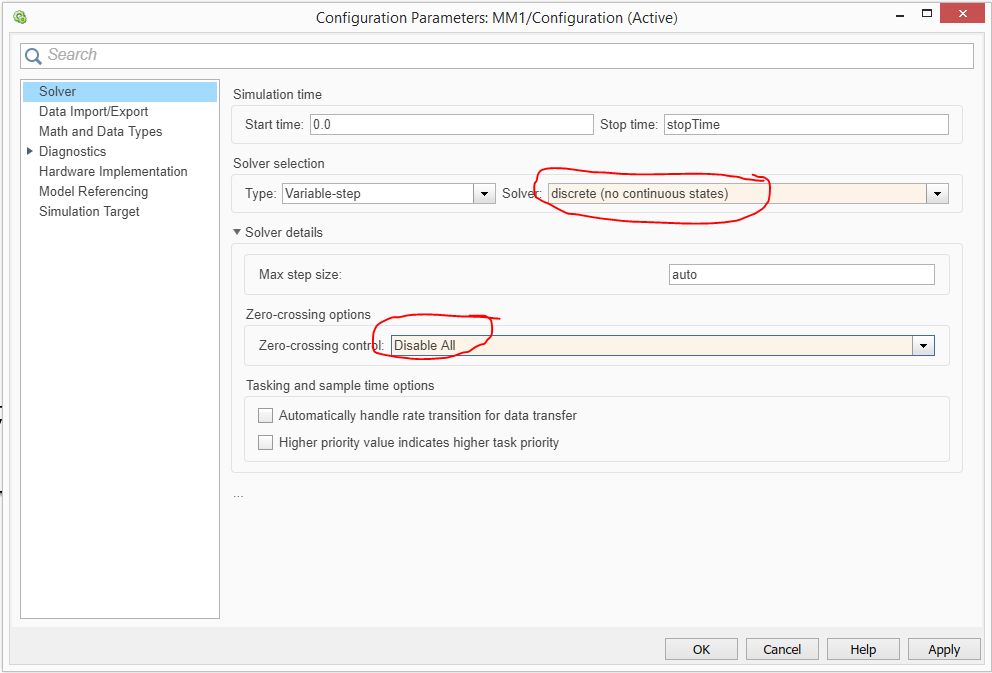

Fig 5. Settings for the simulation engine and solver

In order to run a simulation, we only have to initialize our parameters and perform a "sim" command.

Running this for the first time sometimes takes a while, because the Simulink environment also needs to be loaded.

interArrivalTime.Value = 1.03;
interServiceTime.Value = 1;
stopTime.Value = 500;

mySeed.Value = 42;
SimOut = sim('MM1','ReturnWorkspaceOutputs', 'on')

SimOut =   Simulink.SimulationOutput:

                logsout: [1x1 Simulink.SimulationData.Dataset] 
                   tout: [947x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


Any logged signal can be found as a `timeseries' object in the structure "SimOut.logsout{i}.Values"

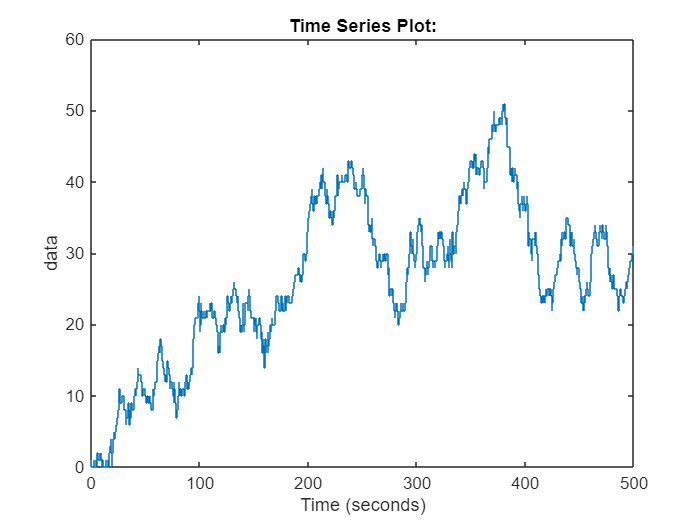

figure;
plot(SimOut.logsout{1}.Values);

### Executing a simulation and a first simple comparison with our expectation

The theoretical distribution studied above was the probability density function $p_n(t)$, for which we conjectured that it would reach a stationary geometric distribution for $t \rightarrow \infty$. To validate this conjecture through simulation we can only hope to find a $t$ that is `large enough', i.e. for which the distribution is close enough to the theoretical steady-state distribution. 

In the analysis below, each run of our simulation model counts as one single 'outcome'. We therefore need to run many separate simulations, and record the result of each. Furthermore, we should use different seeds for different variables within each simulation, and we should make sure these seeds are also different between simulations, otherwise outcomes will not be independent. 

As a basis for comparison, the script below performs the simulations, plots the distribution we found, and also plots the expected distribution based on the theoretical analysis carried out before.

We start out by choosing a relatively low simulation stop-time t=100 and a low number N=5 of outcomes in order to validate our code. The reason for this, is that running the code should not take too long during debugging. Once we are convinced the code runs correctly, we start several other runs with different parameters. In the saved file, I've taken t=1000 and N=50 to give you a feel for how long a typical simulation will take for this type of system - but some experiments really took longer.

Note how the code below is setup of 3 different parts. Firstly, the N simulations we are going to run are prepared in a vector that contains all the simulation settings for each separate simulation experiment. Then we start all the simulations at once (depending on the Matlab toolboxes you have available they may run in parallel or not). And lastly, we pick only the data we need from the output object into an outcomes vector that can be visualized in the next section.

When you start writing your own simulation code, of course the most important part to think about is how to prepare the different simulations you want to run. You sometimes also may want to interrupt simulations if your machine runs out of memory to store intermediate results. For our purpose in this file, that was not necessary. But as you will find out, some simulations take a long time, and some use a lot of memory. Talk to fellow students if you have trouble optimizing for performance, there are always some that have cool ideas.

% DO NOT COPY CODE FROM THIS EXAMPLE FILE - WRITE YOUR OWN!

clear("all")

t   = 100; % Simulation stop time - default 100
iat = 1.25; % Interarrival time - default 1.25
ist = 1.0; % Interservice time - default 1

N = 20; % Number of simulations

modelname = 'MM1'; % Spoiler alert... later this is changed into 'MM1corrected'

% Define a vector of simulation parameters, one for each run
for i = 1:N
  in(i) = Simulink.SimulationInput(modelname);
  in(i) = in(i).setVariable('stopTime', t);
  in(i) = in(i).setVariable('interArrivalTime', iat);
  in(i) = in(i).setVariable('interServiceTime', ist);
  % Seeds are chosen in steps of 2 because the model internally 
  % uses mySeed and mySeed+1 as different seeds for different
  % random generator - ensuring independence of interarrival times
  % and service times. Seeds between runs should not overlap.
  in(i) = in(i).setVariable('mySeed', 2*i);
end

% Run all simulations in parallel
out = parsim(in)

[08-Feb-2025 16:00:48] Checking for availability of parallel pool...
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.
[08-Feb-2025 16:01:14] Starting Simulink on parallel workers...
[08-Feb-2025 16:01:18] Configuring simulation cache folder on parallel workers...
[08-Feb-2025 16:01:19] Loading model on parallel workers...
[08-Feb-2025 16:01:27] Running simulations...
[08-Feb-2025 16:01:49] Completed 1 of 20 simulation runs
[08-Feb-2025 16:01:49] Received simulation output (size: 10.38 KB) for run 1 from parallel worker.
[08-Feb-2025 16:01:49] Completed 2 of 20 simulation runs
[08-Feb-2025 16:01:49] Received simulation output (size: 9.62 KB) for run 2 from parallel worker.
[08-Feb-2025 16:01:49] Completed 3 of 20 simulation runs
[08-Feb-2025 16:01:49] Received simulation output (size: 9.30 KB) for run 3 from parallel worker.
[08-Feb-2025 16:01:49] Completed 4 of 20 simulation runs
[08-Feb-2025 16:01:49] Received simulation out

out = 1x20 Simulink.SimulationOutput array




% Run all simulation sequentially if you don't have the parallel
% computation toolbox installed...
%
% out = sim(in)
%

% Process the outcomes by picking the last element of each simulation
outcomes = zeros(1,N);
for i = 1:N
    outcomes(i) = out(i).logsout{1}.Values.Data(out(i).logsout{1}.Values.Length);
end

% The end-result is a vector
outcomes

outcomes =      3     1     1     0     8     0     5     0     1     2     1     0     2     0     0     8     0     8     0     1


### Visualisation of the results

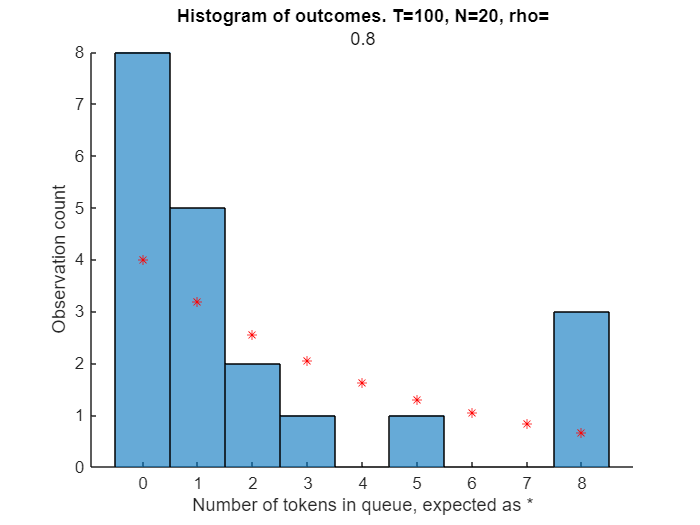

% Let's draw a histogram of the outcomes and overlay a plot of the 
% expected geometric distribution in red stars
figure;
  hold on;
  max_outcome = max(outcomes);
  histogram(outcomes,-0.5:max_outcome+0.5); % histogram of outcomes
  plot(0:max_outcome,geopdf(0:max_outcome,1-ist/iat)*N,'r*'); % expected geometric distribution
  title("Histogram of outcomes. T="+t+", N="+N+", rho=",ist/iat)
  xlabel("Number of tokens in queue, expected as *")
  ylabel("Observation count")  

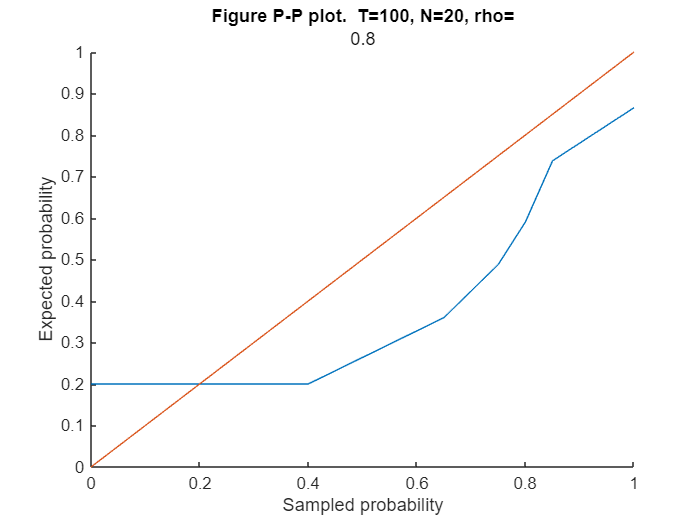


% The function "ecdf" can provide you with a cumulative density plot of
% outcomes of an experiment. It returns a vector of probabilities P and
% corresponding quantiles Q.
[P,Q] = ecdf(outcomes);

% For the expected geometric distribution, we can find comparable
% probabilities and quantiles.
P_expected = geocdf(Q,1-ist/iat); % the geometric cumulative distribution
Q_expected = geoinv(P,1-ist/iat); % the geometric inverse cdf

% Using these vectors, we can draw the P-P and Q-Q plots to get insight in
% how far the two distributions are apart.
figure
  hold on
  plot(P,P_expected) % P-P plot
  plot([0,1],[0,1]) % Compare to the unit line
  title("Figure P-P plot.  T="+t+", N="+N+", rho=",ist/iat)
  xlabel("Sampled probability")
  ylabel("Expected probability")

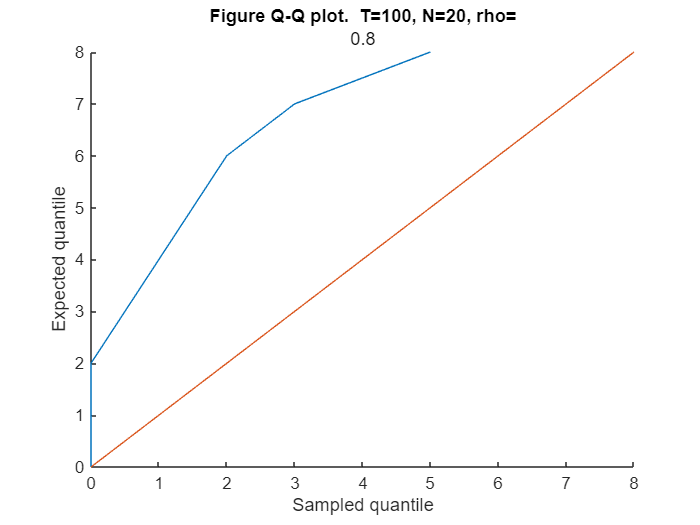


figure
  hold on
  plot(Q,Q_expected) % Q-Q plot
  plot([0,max(Q)],[0,max(Q)]) % Compare to the unit line
  title("Figure Q-Q plot.  T="+t+", N="+N+", rho=",ist/iat)
  xlabel("Sampled quantile")
  ylabel("Expected quantile")

## Varying a few parameters: three different plots, suspicion of a bug

Now that we have working simulation code, the next step is to run sufficiently many simulations to convince ourselves that 1) the simulation time we have chosen is large enough to have reached a stable distribution, and 2) the distribution contains enough elements to reliably perform a $\chi^2$ goodness-of-fit test.

In order to get a feeling for what good parameters are, we will have to run a few simulations with some extreme values. We start with small values in order to catch little mistakes in our method early, and move on to larger values when we get more confident. The reason for this, is that larger values lead to longer simulation times, and we can only afford to wait this long if we know we are on the right track.

### A first attempt: iat = 1.25, ist = 1, T = 100, N = 50

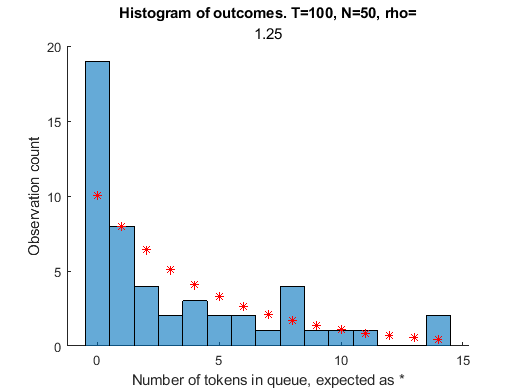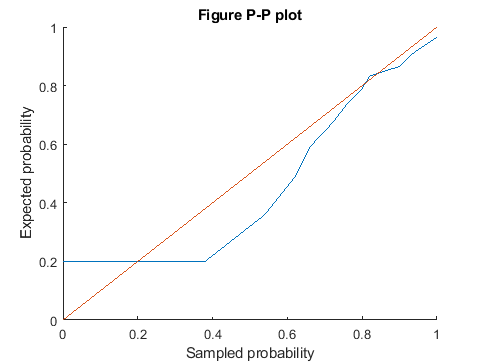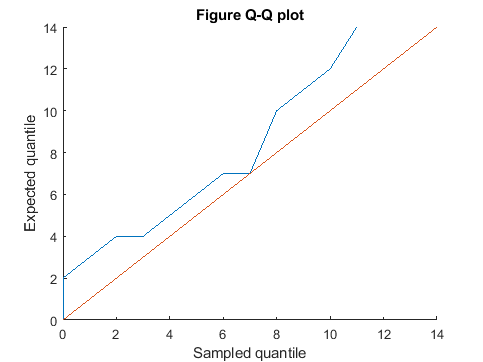

Fig. 6 Simulated distribution for iat = 1.25, ist = 1, T = 100, N=50 (expected = red, simulated = blue)

Our first set of 50 simulations clearly shows a higher than expected peak at 0 (see Fig. 6). This suggests that we are not simulating long enough to have reached steady state - after all, if we are not running long enough simulations the system does not have time to "fill up". We decide not to carry out a $\chi^2$ test yet, since the difference is too clear and we would like to run a few longer simulations first.

### Further attempt: iat = 1.25, ist = 1, 10^6, N = 50

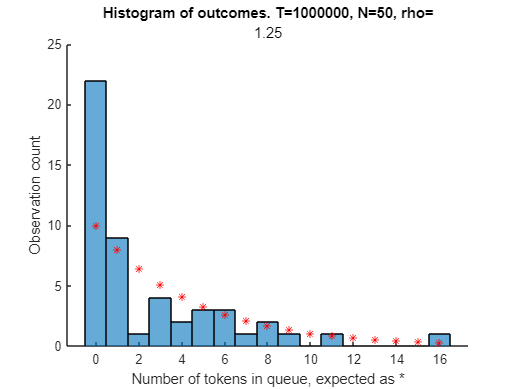

Fig. 7 Simulated distribution for iat = 1.25, ist = 1, T = 10^4 (left) and 10^6 (right), N=50 (expected = red, simulated = blue)

When we increase the simulation time to 10^4 or even 10^6, we expect that some of the peak at 0 will distribute to the right. However, we mostly get a similar result to the case where T = 100. For the case 10^4 we do get a bit of a higher count (21), and for the case 10^6 we get a bit more even spread, but the number times a buffersize of 0 is observed remains way too large. 

Obviously, these experiments took a longer time, so it is necessary now to think a little bit about whether we need to push for even longer simulation times. Of course, it is possible that the time-constants of this system are such that they require even longer simulations. But if we consider that the system has a utilisation of $\rho = \frac{ist}{iat} = 0.8$, the average buffer-size is given by $\frac{\rho}{1-\rho} = 4$, and therefore the expected time a token stays in the system is $\frac{\rho}{1-\rho}*iat = 5$, it is rather unexpected that 10^6 would be insufficient to reach steady-state. We decide to focus our next experiment on trying different values for $\rho$. In particular, we will choose the inter-arrival time closer to the inter-service time in order to increase the expected number of tokens in the buffer. This should decrease the peak at 0 even for shorter simulation times.

### One more experiment: iat = 1.05, ist = 1, t = 10^4, N = 50

In order to be certain that something is wrong, and maybe get an idea for what is wrong, let's do an experiment for which we would expect to see a higher degree of buffer filling from the start.

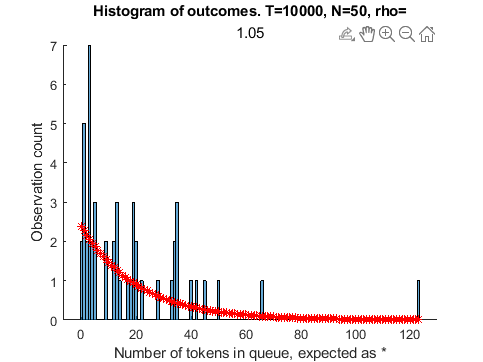

Fig 8.  Simulated distribution for iat = 1.05, ist = 1, T = 10^4, N=50 (expected = red, simulated = blue)

As one can see in Fig. 8, the desire to obtain higher buffer fillings has been fulfilled. However, the choice of $\rho = 0.95$ also means a much higher variance in outcomes. As a result, N = 50 does not seem to provide us with a recognizable distribution at all. Recall, that for a meaningful execution of a $\chi^2$ test, one needs at least 5 elements in every bin, while many of the bins in this figure are still empty. Of course, if theory and simulation do not align, there might be a non-statistical reason why they are empty, but let's first see if we can get a better distribution by taking a higher number of experiments. At the same time, we lower the value of T in order to keep our waiting time acceptable. If it turns out that we still have a steady-state problem, we can increase it again later.

### A cleaner distribution at: iat = 1.05, ist = 1, t = 10^3, N = 500

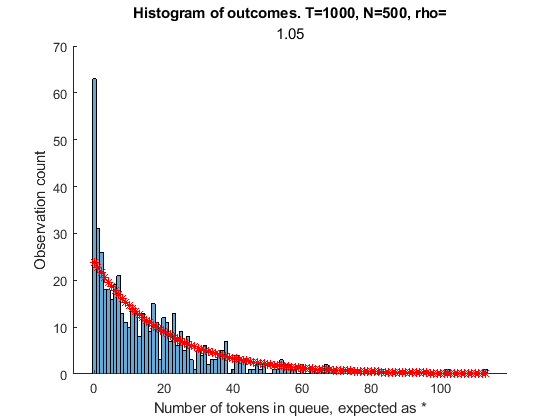

Fig 9. Simulated distribution for iat = 1.05, ist = 1, T = 10^3, N=500 (expected = red, simulated = blue)

When we increase the number of simulations, we start to see a better distribution, but also the unexplained high value at 0 returns.

At this point, there are two strategies on how to continue:

1) We could re-evaluate our model, asking others to have a look at it.

2) We could implement a goodness-of-fit test to eliminate the possibility that the high peak at 0 is coincidental.

Because we have seen it occur consistently in quite a few experiments, we decide on strategy 1) for now.

## Solving the bug

So our mathematical model appears not to match our simulation model. The problem when theory and simulation do not match, is that there is not a single method that will lead to a solution. 

Now, there is a story about Archimedes who had to determine the volume of the Kings crown without destroying it, because he needed to prove it was pure gold. He had no clue how to do it, until his wife told him to relax and take a bath... of course, he took the crown with him, and saw the water rise when it went under... the rest is history (including the part where he runs happily through the streets of Athens shouting "Eureka", while his wife was shouting "your towel!") The moral of that story is - always listen to your wife... 

So when I asked my wife, her first question to me was: why are you not counting the number of tokens in the server? (She is a very practical person who happens to know a bit more about engineering than Archimedes' wife... I'm blessed). Of course... she was absolutely right.

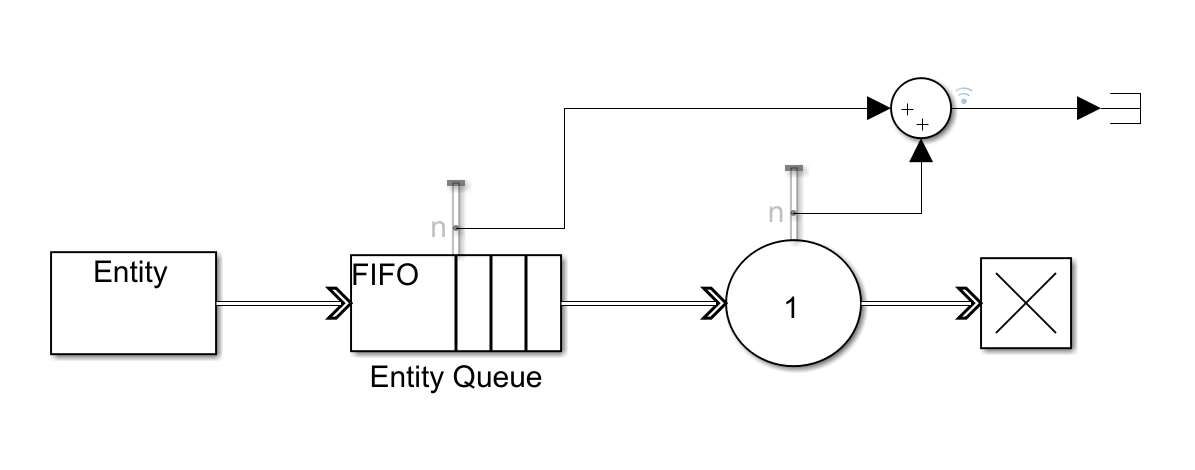

Fig 10. Updated simulation model of an M/M/1 queue

The theory on our M/M/1 queue does not involve the number of tokens in the queue, but rather calculates the number of tokens in the system as a whole. Tokens generated in the entity generator immediately end up in the queue, but tokens being processed by the server are still in the system while being processed. We did not count these, which explains why we more often count 0 tokens than expected. Whenever there is 0 or 1 token in the system, it shows up as 0 tokens in the buffer, whenever there are 2 tokens in the system, it shows up as 1 token in the buffer, etc.

Of course, we could try to update the theory to fit the simulation model... but in this case it is easier to fit the simulation model to the theory (see Fig. 10).

After updating the modelname in the script above to 'MM1corrected' (try it!) we can play around with the model a little more.

## Second attempt: studying the effect of warm-up time

### A renewed attempt: iat = 2.25, ist = 1, T = 100, N = 50

For our first attempt, we revert to the case where iat = 2.25 and ist = 1, so that N = 50 will give a reasonable spread already as the expected buffer fillings are low. We also revert to T = 100 to get a quick result.

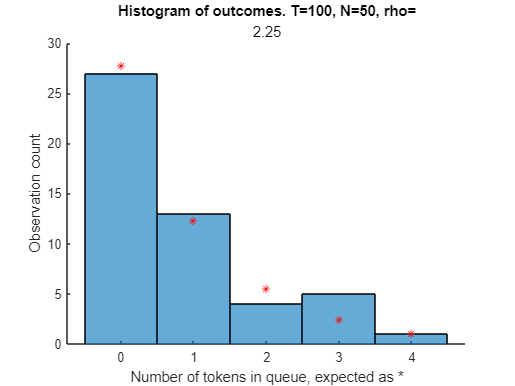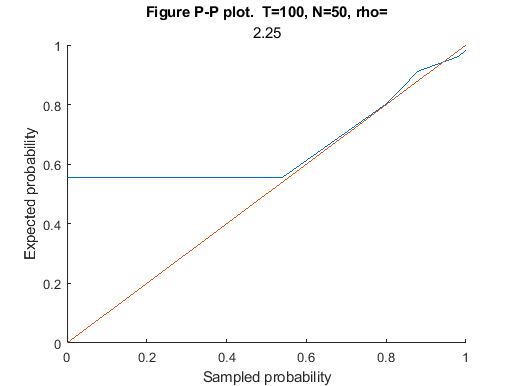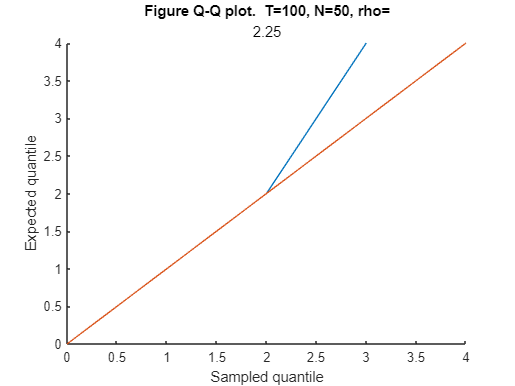

Fig 11. Corrected simulated distribution for iat = 2.25, ist = 1, T = 100, N=50 (expected = red, simulated = blue)

As one may see in Fig. 11, the simulated distribution is now much closer to the expected distribution. There is a big jump in the Q-Q plot, due to the fact that we only have a few measurements, so we expect a relatively large deviation at the tail of the distribution. 

Still, we are aware of the fact that the 'warm up' period of the simulation, i.e. the time needed for the system to reach steady state, might influence our results greatly. We therefore will run a few experiments to get a feeling for how long the warm up period should be. Be aware, that the warm-up time depends on the chosen parameters of the system, so the investigation below would need to be repeated if we are interested in, for example, a different inter-arrival time.

### Illustration of the effect of warm-up: iat = 1.25, ist = 1, T in {5, 50, 500,5000}, N = 250

In order to investigate the effect of warm-up, we choose an iat = 1.25 and ist = 1. This is expected to give a slightly larger average buffer size of 4. Because larger buffersizes are expected, we should be able to see the difference between a 'too short' simulation in which these buffersizes are not frequently attained, and a 'long enough' simulation, in which they are. After all, it takes time to fill the buffer, and in too short simulations this time is not provided. We increase the number of simulation to 250 to obtain 'smoother' distributions, and we vary the simulation length to see if the expected effect is indeed visible.

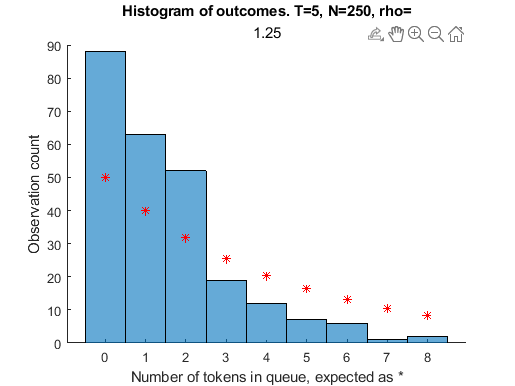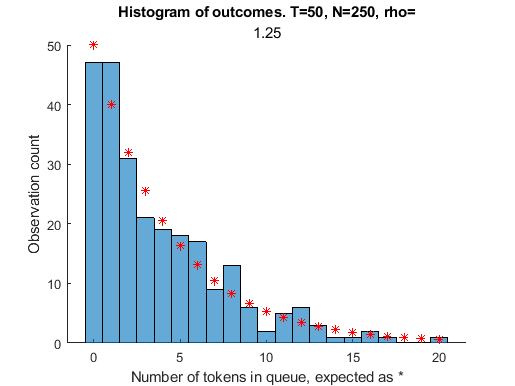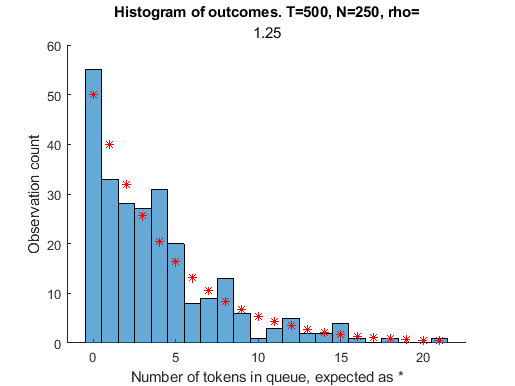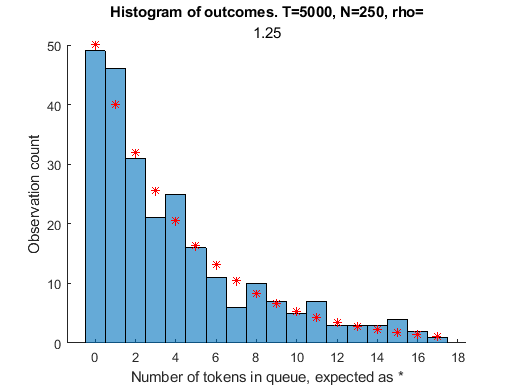

Fig 12. Corrected simulations for iat = 1.25, ist 1, N = 5 illustrating the effect of the warm-up period by choosing t in {5,50,500,5000} (expected = red, simulated = blue)

Figure 12 shows that, as expected, we see for low values of t that the distribution is higher than the theoretical distribution to the left and lower than the theoretical distribution to the right. For values of t=500 and t=5000, we do not see significant differences at first sight. This hints at the possibility that the system has reached steady state, which we might confirm by performing a goodness-of-fit test. Of course, better fits will probably still occur if we increase the number of simulations N.

## Third comparison: using goodness-of-fit tests

Now that we have confirmed, by visual inspection, that there are no blatant discrepancies between the theoretical distribution and the simulation, it is time to take a more systematic look at out results. As soon as theory and simulation become a closer fit, we need more precise methods of recognizing whether the fit is according to expectation with a certain level of confidence. As an illustration of these tests, let's have a look again at the way in which the distribution becomes a closer fit when the simulation time becomes larger. We adapt our script to remember the distributions that were found, and subsequently apply a $\chi^2$ test to them. 

clear("all")
tic % start a stopwatch to measure the running time of this script

t   = [1,5,25,50,250,500,1000,2500]; % Simulation stop time as a vector
iat = 1.25; % Interarrival time - default 1.25
ist = 1.0; % Interservice time - default 1

N = 250; % Number of simulations

modelname = 'MM1corrected';

% Define a vector of simulation parameters, one for each run
for i = 1:N
    for j = 0:size(t,2)-1
        in(j*N+i) = Simulink.SimulationInput(modelname);
        in(j*N+i) = in(j*N+i).setVariable('stopTime', t(j+1));
        in(j*N+i) = in(j*N+i).setVariable('interArrivalTime', iat);
        in(j*N+i) = in(j*N+i).setVariable('interServiceTime', ist);
        in(j*N+i) = in(j*N+i).setVariable('mySeed', 2*(j*N+i));
    end
end

% Run all simulations in parallel
out = parsim(in)

[08-Feb-2025 16:02:09] Checking for availability of parallel pool...
[08-Feb-2025 16:02:10] Starting Simulink on parallel workers...
[08-Feb-2025 16:02:10] Configuring simulation cache folder on parallel workers...
[08-Feb-2025 16:02:11] Loading model on parallel workers...
[08-Feb-2025 16:02:14] Running simulations...
[08-Feb-2025 16:02:27] Completed 1 of 2000 simulation runs
[08-Feb-2025 16:02:27] Received simulation output (size: 7.28 KB) for run 1 from parallel worker.
[08-Feb-2025 16:02:27] Completed 2 of 2000 simulation runs
[08-Feb-2025 16:02:27] Received simulation output (size: 7.26 KB) for run 2 from parallel worker.
[08-Feb-2025 16:02:27] Completed 3 of 2000 simulation runs
[08-Feb-2025 16:02:27] Received simulation output (size: 7.26 KB) for run 3 from parallel worker.
[08-Feb-2025 16:02:27] Completed 4 of 2000 simulation runs
[08-Feb-2025 16:02:27] Received simulation output (size: 7.26 KB) for run 4 from parallel worker.
[08-Feb-2025 16:02:27] Completed 5 of 2000 simulati

out = 1x2000 Simulink.SimulationOutput array




% Process the outcomes by picking the last element of each simulation
outcomes = zeros(size(t,2),N);
for j = 0:size(t,2)-1    
    for i = 1:N
      outcomes(j+1,i) = out(j*N+i).logsout{1}.Values.Data(out(j*N+i).logsout{1}.Values.Length);
    end
end

% Let's save the outcomes of our results, so that we do not have to
% generate them again whenever we want to change something in the next
% section.
save("SimulationResults","outcomes","t","iat","ist","N","modelname")

% Having separate sections makes it easier to separate work.
% Let's start this section by loading the simulation results again.
load("SimulationResults")

% Choose a confidence level
confidence = 0.99; 
% Choose a set of bins - we now pick 7 bins centered around 0..5 and [5.5, inf)
B = [0:2 inf]-0.5; 
% The critical value of the chi2gof test, degrees of freedom = number of bins - 1
critical_value = chi2inv(confidence,size(B,2)-1) 

critical_value = 11.3449


% Initialize our output arrays
chi2value = zeros(size(t)); % Array that keeps track of actual chi2values found
chi2test = zeros(size(t)); % Initialize to 0
for j = 1:size(t,2)
  % Recover total number of experiments N from outcomes
  N = size(outcomes,2);  
  % Count the number of occurrences in each of the bins
  out_count = histcounts(outcomes(j,:),B);
  % Determine the expected number op occurrences in each of the bins  
  expected_count = diff([geocdf(B,1-ist/iat)]);
  % Compute the chi2value
  chi2value(j) = sum(((out_count - (expected_count*N)).^2)./(expected_count*N),2);
  chi2test(j) = chi2value(j) > critical_value;
end
chi2test

chi2test =      1     1     0     0     0     0     0     0



% For educational purposes, I also give some alternative code below to compute 
% the same chi2value uses a cell-array {@geocdf,1-ist/iat} as input to the 
% chi2gof function from MATLAB. However, be careful here.
% The implementation of chi2gof is pessimistic in its choice of degrees of
% freedom - it uses a different method for computing degrees of freedom that
% is actually more tuned to "fitted" distributions and a-posteriori computation
% of appropriate binning. As a consequence, the "h" value that comes out of the 
% test tends to sometimes reject the outcome even if it should not according to
% the theory discussed in our course. If you look at the stats, you'll see that 
% it estimates "df=1" while df should be equal to the number of bins - 1. 
% Given the circumstances of the input, I consider this a bug in MATLAB - or at 
% the very least an unclarity in how to use the chi2gof function.
%
% The chi2stat statistic is computed correctly however, so we can use the
% function to perform a chi2gof test for us, as long as we compare the
% outcome ourselves instead of relying on the internal computation of 'h'.

chi2value2 = zeros(size(t)); % Array that keeps track of actual chi2values found
chi2test2 = zeros(size(t)); % Initialize to 0
for j = 1:size(t,2)
  [h,p,stats] = chi2gof(outcomes(j,:),"CDF",{@geocdf,1-ist/iat},'Alpha',1-confidence,'Edges',B,'Emin',5);
  chi2value2(j) = stats.chi2stat;
  chi2test2(j) = chi2value2(j) > critical_value;
end
chi2test2

chi2test2 =      1     1     0     0     0     0     0     0


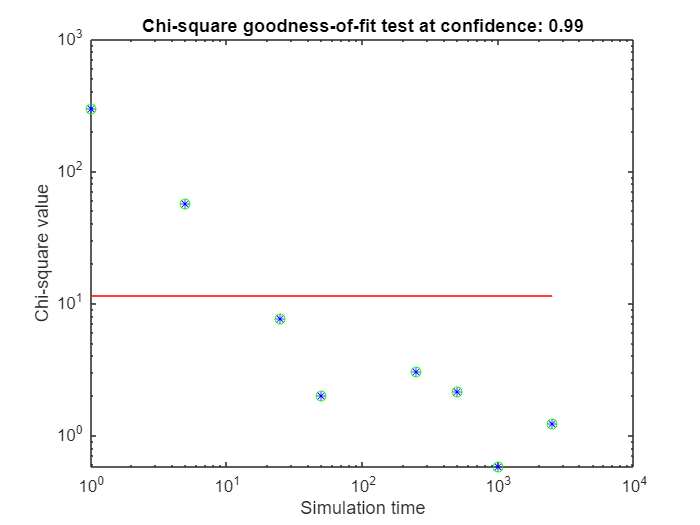


figure    
  loglog(t,chi2value,'b*')
  hold on
  loglog(t,chi2value2,'go')  
  loglog(t,critical_value*ones(size(t)),'r')
  title("Chi-square goodness-of-fit test at confidence: "+confidence)
  ylabel("Chi-square value")
  xlabel("Simulation time")


toc % provides the total time it took to run this part of the script

Elapsed time is 1302.016108 seconds.


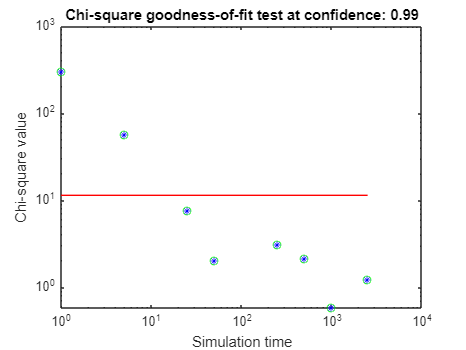

As you can see, for t >= 50, the $\chi^2$ value drops below the calculated threshold, which corresponds to a confidence level of 99%. We observe that, once simulation time exceeds 100, our simulations do not provide evidence anymore of any difference between theory and simulation. For values smaller than t = 50, the differences are statistically relevant, and we attribute this to the fact that the system has not passed its warm-up time yet.

Also, we observe that for longer simulation times, our confidence in the theory does no longer increase. We hypothesize, that increasing our confidence in the theory further may be achieved by increasing the number of simulations, but at the moment of this writing we do not have time to pursue experiments in that direction.

## Concluding remarks

In this LiveScript, we have outlined the theoretical distribution of tokens at steady state in an M/M/1 queue, and we have simulated the same. We have illustrated how for small simulation times a discrepancy between theory and simulation can be detected using Chi-squared tests, and how this becomes increasingly more difficult for higher simulation times. 

This script contains many remarks and hints that are intended to make students of simulation methods think about various aspects of simulation, and there are still many axes of further investigation left to uncover. In particular, in the upcoming assignments of the course we will see considerably faster methods for simulation of processes that are ergodic.

### Reflection and future work

In order for this script to contain a convincing study of the M/M/1 queue, it would be good if we had included a broader range of parameters. Values of $\rho$ close to 0 and close to 1 would need to be investigated, as well as values in the middle. Furthermore, theoretically it is only the value of $\rho$ that matters for the stationary distribution, but in the model an inter-arrival time and an inter-service time are chosen that, together, determine $\rho$. If both these times are scaled by a certain factor, the stationary distribution should not change. We did not validate if this is indeed the case for our model. 

Future work on this model will firstly include an extension of the model to also consider M/M/1/k - bounded queues. After that, an investigation into the Batch method seems worthwhile. Since the M/M/1 queue is an ergodic system, long run simulation methods like the Batch method can be applied to considerably speed up the simulation of the system. This will make it much easier to do further experiments. 

This work is intended to be a 'worthy example' of what is expected from students when they report on their own work at 'advanced' level. It does, however, 'lack' in points that are considered 'master' or 'expert' level. This script does not go 'beyond' the material of this course in any way. It does not refer to external sources, nor does it implement anything original except, perhaps, the use of the parallel computation toolbox and a bit of understanding of the build-in functions that MATLAB provides.

#### Reflection on my own Matlab skills

As work on this course proceeds, I'm getting more proficient in Matlab myself. The first versions of this script only used self-written routines. By now, I am able to use and understand the build-in functions better. Still, I am convinced that it may help students to avoid using the build-in functions while they study the topic. Once procedures like the chi-square goodness of fit test are understood, one can better understand the documentation of the chi2gof function - and judge which parameters are relevant and which are not. Although I must say that even with experience, this is not always easy. 

### Acknowledgements

I am indebted to Adam Watkins for going through earlier versions of this script and discussing its contents and quality with me. Furthermore, I would like to thank students Stefan Willigers and Rahul Ramesh for (after impressive debugging) pointing out a mistake in earlier versions of my code, and Nikola Felkaroski for pointing out ways to use the parallel processing toolbox.